Piotr Sienkiewicz    324 887

Tadeusz Chmielik   324 856

## Generowanie sygnału stacjonarnego

Proszę wygenerować sygnał będący mieszaniną trzech sygnałów sinusoidalnych (najlepiej użyć *cos*) o różnych wzmocnieniach, fazach i częstotliwościach. Sygnał powinien być próbkowany z częstotliwością 1 kHz i mieć długość 2 sekund.

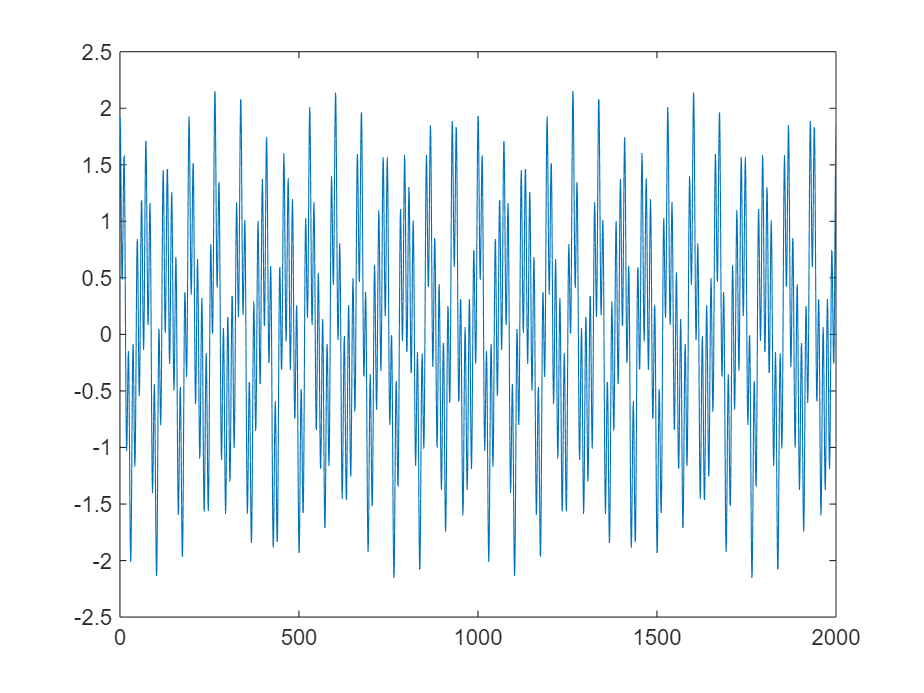

% Parametry systemu
Fs = 1000;     % Częstotliwość próbkowania [Hz]
T = 1/Fs;      % Okres próbkowania [s]
L = 2000;      % Długość sygnału (liczba próbek)
t = (0:L-1)*T; % Podstawa czasu

% Przygotowanie sygnału
N = 3;               % Liczba sinusoid w mieszaninie
A = [1.0   0.4  0.8]; % Amplitudy kolejnych sinusoid
B = [ 15    27   83]; % Częstotliwości kolejnych sygnałów [Hz]
C = [  0 -pi/3 pi/7]; % Przesunięcia fazowe kolejnych sygnałów


x = zeros(size(t));
for i = 1:N
  x = x + A(i) * cos(2 * pi * B(i) * t + C(i));
end

plot(x);

## Transformata Fouriera sygnału niezaszumionego

Sygnał wygenerowany w poprzednim kroku proszę przekazać do funkcji liczącej transformatę fouriera FFT. Wynik transformaty proszę przedstawić w postaci wykresu aplitudy i fazy sygnałów. Z wykresów proszę odczytać dominujące częstotliwości w sygnale, ich wzmocnienie oraz fazę. Wyniki proszę porównać z wartościami oczekiwanymi (zdefiniowanymi przy generowaniu sygnału).

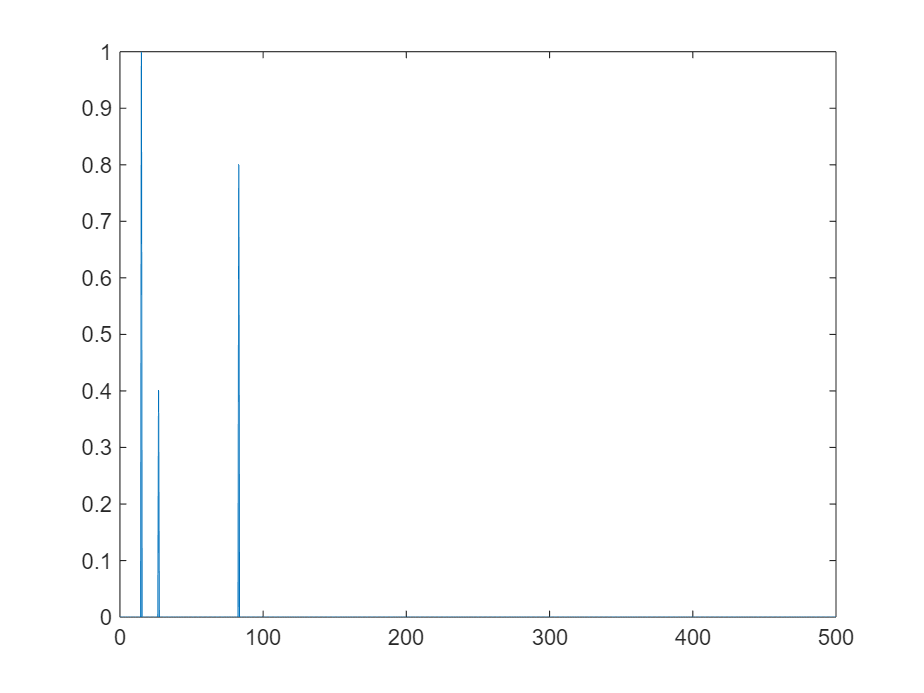

Y = fft(x);     % transformata Fouriera

Amp = abs(Y);     % amplituda sygnału
Amp = Amp/L;        % normalizacja amplitudy

Amp = Amp(1:L/2+1); % wycięcie istotnej części spektrum
Amp(2:end-1) = 2*Amp(2:end-1);

Phi = angle(Y);   % faza sygnału
Phi = Phi(1:L/2+1); % wycięcie istotnej części spektrum


f_step = Fs/L;     % zmiana częstotliwości
f = 0:f_step:Fs/2; % oś częstotliwości do wykresu

figure;
plot(f, Amp);        % wykres amplitudowy

Poniższy kod służy zweryfikowaniu, czy algorytm FFT działa zgodnie z oczekiwaniami. Wyświetla znalezione piki amplitudy oraz przyporządkowane im częstotliwości.

[top_values, indices] = maxk(Amp, 3);
f_top_values = f(indices);

result = [f_top_values; top_values]; 

fprintf(['Częstotliwość [Hz] | Amplituda\n' ...
           '-------------------|----------\n' ...
           '%18.2f | %8.4f\n' ...
           '%18.2f | %8.4f\n' ...
           '%18.2f | %8.4f\n'], result);

Częstotliwość [Hz] | Amplituda
-------------------|----------
             15.00 |   1.0000
             83.00 |   0.8000
             27.00 |   0.4000


Jak widać wszystko działa poprawnie, gdyż wartości amplitud i częstotliwości są zgodne z tymi używanymi podczas generowania sygnałów sinusoidalnych.

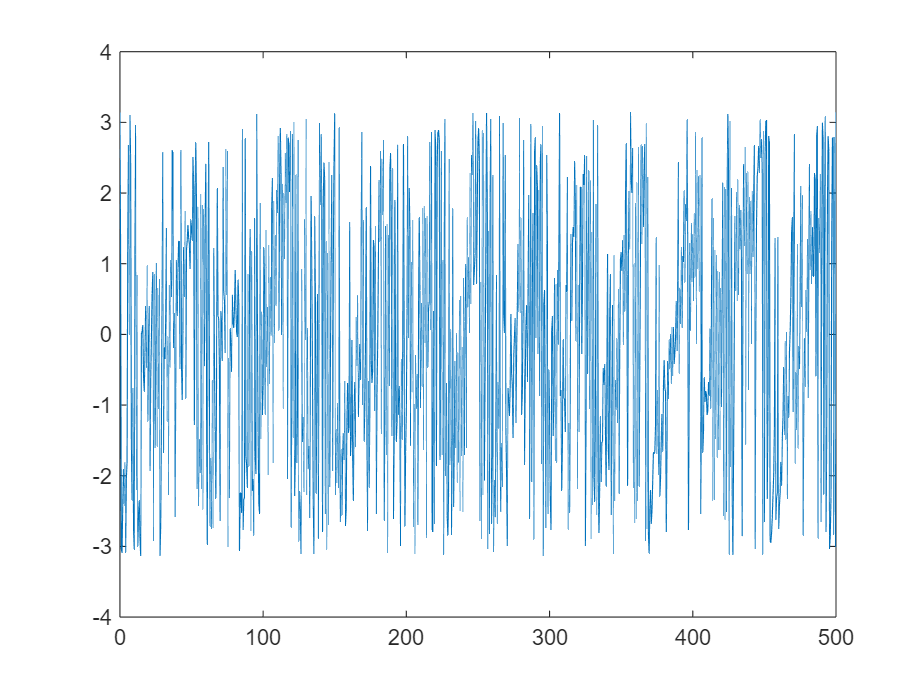

figure;
plot(f, Phi);        % wykres fazowy

phi_values = Phi(indices);
result = [f_top_values; phi_values]; 

fprintf(['Częstotliwość [Hz] | Faza\n' ...
           '-------------------|----------\n' ...
           '%18.2f | %8.4f\n' ...
           '%18.2f | %8.4f\n' ...
           '%18.2f | %8.4f\n'], result);

Częstotliwość [Hz] | Faza
-------------------|----------
             15.00 |  -0.0000
             83.00 |   0.4488
             27.00 |  -1.0472


I w tym przypadku wszystko się zgadza, gdyż sygnały miały fazy 0, -π/3 oraz π/7 (w tym przypadku zmieniona jest jedynie kolejność częstotliwości ze względu na to, że funkcja maxk sortuje znalezione dane nie po rosnących indeksach, a po malejącej wartości).

## Generowanie sygnału zaszumionego

 W tym zadaniu wygenerowano sygnał szumu o odchyleniu standardowym 3 razy większym niż amplituda największej harmonicznej badanego sygnału, a następnie dodano go do niego.

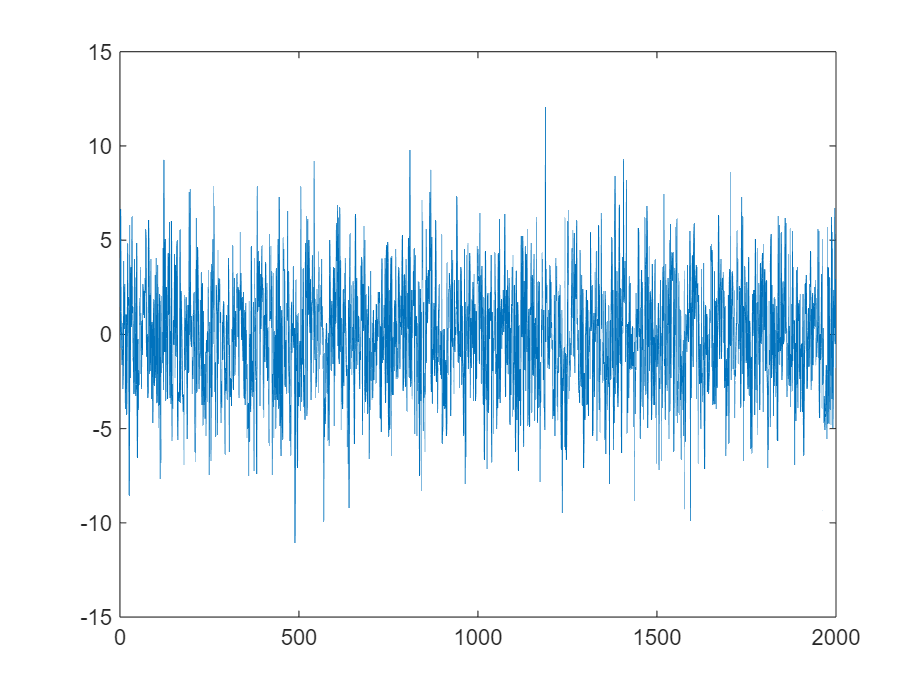

noise = 3 * randn(size(x));
noised_x = x + noise;
plot(noised_x);

Jak widać, w tym przyapdku sygnał w dziedzinie czasu w ogóle nie przypomina sygnału badanego w poprzednim podpunkcie.

## T**ransformata Fouriera sygnału zaszumionego**

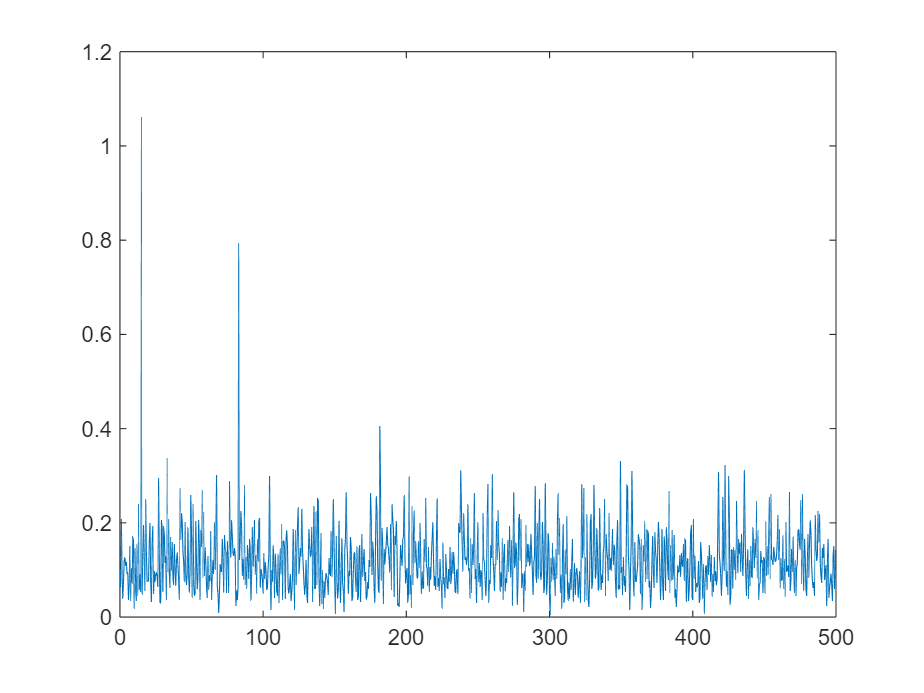

Y_noised = fft(noised_x);     % transformata Fouriera

Amp_noised = abs(Y_noised);     % amplituda sygnału
Amp_noised = Amp_noised/L;        % normalizacja amplitudy

Amp_noised = Amp_noised(1:L/2+1); % wycięcie istotnej części spektrum
Amp_noised(2:end-1) = 2*Amp_noised(2:end-1);

Phi_noised = angle(Y_noised);   % faza sygnału
Phi_noised = Phi_noised(1:L/2+1); % wycięcie istotnej części spektrum


f_step = Fs/L;     % zmiana częstotliwości
f = 0:f_step:Fs/2; % oś częstotliwości do wykresu

figure;
plot(f, Amp_noised);        % wykres amplitudowy

Na widmie sygnału widać dużą ilość szumu, ale jako że ma on rozkład równomierny, to i jego energia jest równomiernie rozłożona w całym paśmie, dlatego też mimo znacznej jego amplitudy można zauważyć piki odpowiadające poszukiwanym harmonicznym sygnału użytecznego.

[top_values_noised, indices_noised] = maxk(Amp_noised, 3);
f_top_values_noised = f(indices_noised);

result = [f_top_values_noised; top_values_noised]; 

fprintf(['Częstotliwość [Hz] | Amplituda\n' ...
           '-------------------|----------\n' ...
           '%18.2f | %8.4f\n' ...
           '%18.2f | %8.4f\n' ...
           '%18.2f | %8.4f\n'], result);

Częstotliwość [Hz] | Amplituda
-------------------|----------
             15.00 |   1.0598
             83.00 |   0.7927
            181.50 |   0.4056


Tym razem wartości amplitud owych harmonicznych nie zgadzają się z rzeczywistymi wartościami używanymi do generacji użytecznego sygnału badanego (szum jest losowy, a więc dla różnych wywołań programu uzyskuje się różne wyniki, raz mniejsze, raz delikatnie większe niż wartości oryginalnych amplitud). Wynika to z dodania do sygnału szumu o dużej amplitudzie, co powoduje rozmycie energii w widmie. Tym razem amplituda w widmie poza tymi trzema harmonicznymi nie jest już zerowa, a także i amplituda badanych harmonicznych uległa zmianie. Aby uzyskać dokładniejsze wyniki można by było w tym przypadku na przykład zwiększyć rozmiar N transformaty.

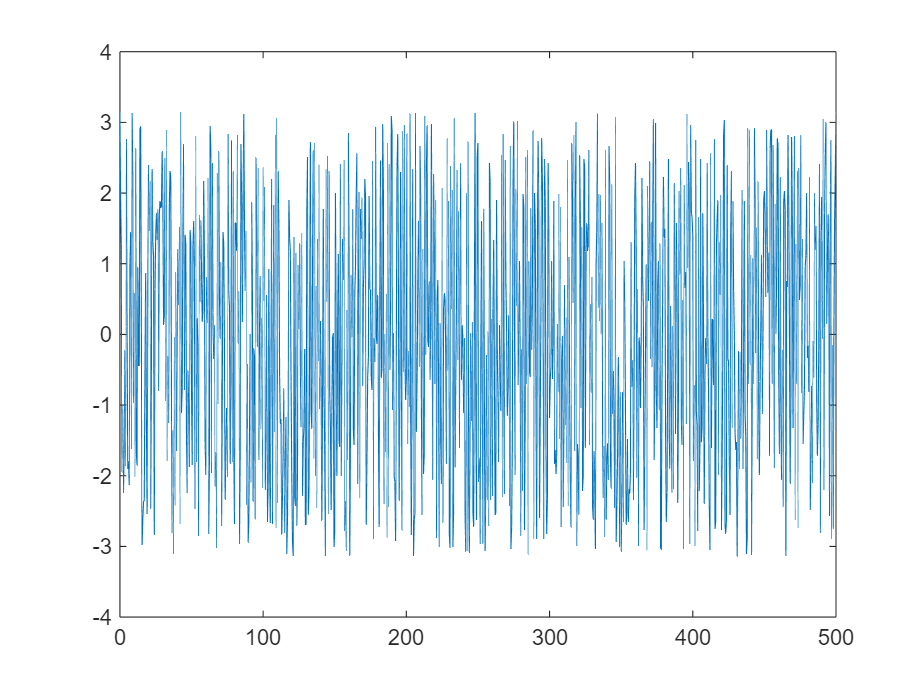

figure;
plot(f, Phi_noised);        % wykres fazowy

phi_values_noised = Phi_noised(indices);
result = [f_top_values_noised; phi_values_noised]; 

fprintf(['Częstotliwość [Hz] | Faza\n' ...
           '-------------------|----------\n' ...
           '%18.2f | %8.4f\n' ...
           '%18.2f | %8.4f\n' ...
           '%18.2f | %8.4f\n'], result);

Częstotliwość [Hz] | Faza
-------------------|----------
             15.00 |   0.0325
             83.00 |   0.6045
            181.50 |  -0.7950


Z powyższych danych wynika, że podobnemu rozmyciu uległa także faza badanego sygnału.

## Analiza tętna

W zadaniu tym zmierzono tętno wykorzystując optyczną metodę i nagranie z poprzednich zajęć, ale tym razem bazowano na algorytmie FFT zamiast na zliczaniu ekstremów.

Poniższy fragment kodu jest identyczny jak ten z poprzednich zajęć.

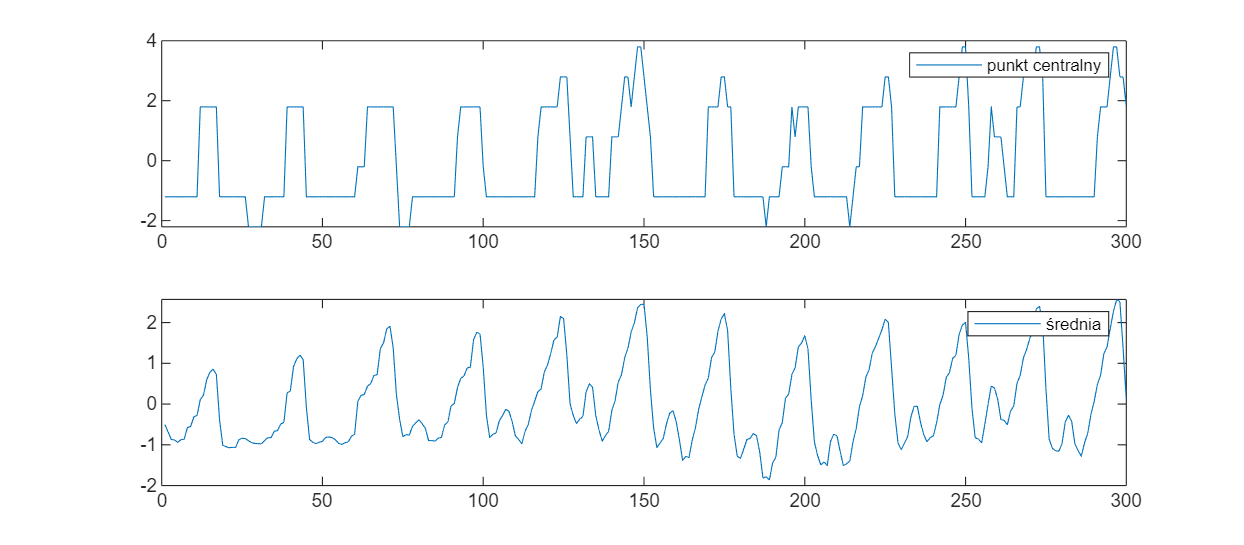

% Liczba ramek do wczytania (przy 10 sekundach i 30 FPS będzie to 300)
N = 300;

% wektor jasności
br = zeros(3, N);

use_video = 1;

if use_video
    % wczytywanie pliku wideo do analizy
    v = VideoReader('data/movie4.mp4');
    % v = VideoReader('data/movie_4.MOV');
else
    % lista obrazów do analizy
    imds = imageDatastore('./data/', 'FileExtension', '.jpg');
end

% wczytanie pierwszych N obrazów i analiza jasności
for i=1:N

    if use_video
        % dla pliku wideo ładowanie ramki z otwartego źródła
        I = read(v,i);
    else
        % wczytujemy obraz
        I = imread(imds.Files{i});
    end

    h = size(I,1);
    w = size(I,2);

    % wybieramy jedynie czerwoną składową obrazu
    I = I(:,:,1);

    % jasność punktu na środku obrazu
    br(1, i) = I(h/2, w/2);

    % wyznaczamy średnią z całego obrazu
    br(2, i) = mean(I, 'all');
end

% dla ułatwienia późniejszej analizy od razu można odjąć od sygnału składową stałą
br = br - mean(br, 2);


h = figure();
set(h,'Units','normalized','Position',[0 0 1 .7]); 
subplot(2,1,1);
plot(br(1,:));
legend('punkt centralny')
subplot(2,1,2);
plot(br(2,:));
legend('średnia');

## Wykonywanie FFT

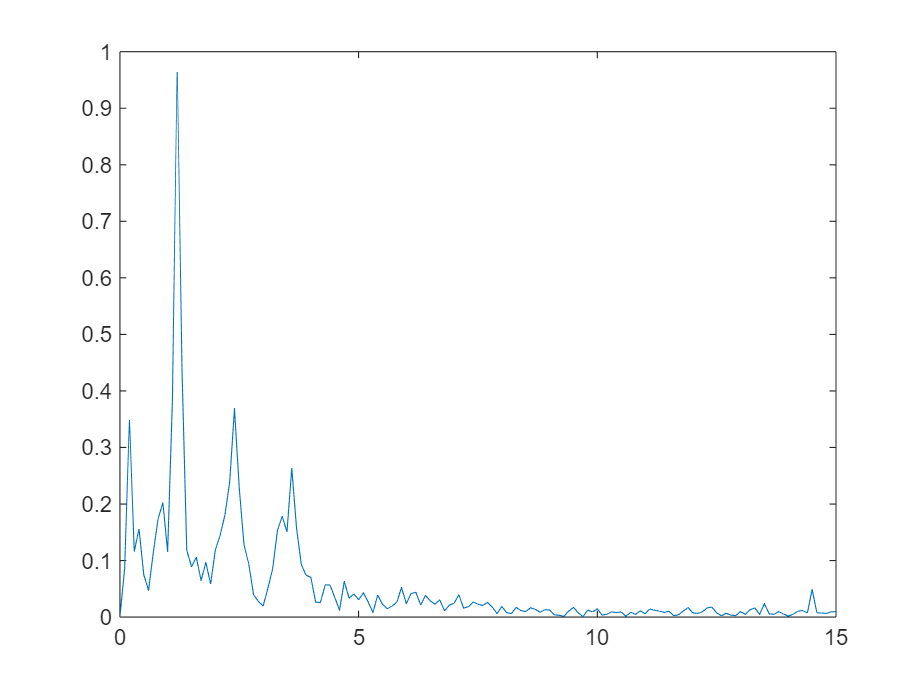

Fs = 30;     % Częstotliwość próbkowania [Hz]
T = 1/Fs;      % Okres próbkowania [s]
L = 300;      % Długość sygnału (liczba próbek)
t = (0:L-1)*T; % Podstawa czasu

Y = fft(br(2,:));     % transformata Fouriera

Amp = abs(Y);     % amplituda sygnału
Amp = Amp/L;        % normalizacja amplitudy

Amp = Amp(1:L/2+1); % wycięcie istotnej części spektrum
Amp(2:end-1) = 2*Amp(2:end-1);

Phi = angle(Y);   % faza sygnału
Phi = Phi(1:L/2+1); % wycięcie istotnej części spektrum


f_step = Fs/L;     % zmiana częstotliwości
f = 0:f_step:Fs/2; % oś częstotliwości do wykresu

figure;
plot(f, Amp);        % wykres amplitudowy

Posiadając widmo można łatwo znaleźć prążek częstotliwości o maksymalnej amplitudzie i przeliczyć tą wartość na BPM, mnożąc daną częstotliwość razy 60. Niestety w przypadku gdy na przykład siła docisku palca do obiektywu się zmieniała podczas nagrania, składowa stała sygnału mogła powoli się zmieniać, co spowodowałoby powstaniem prążka o dużej amplitudzie i bardzo małej częstotliwości. Dlatego dodano do programu zabezpieczenie przed taką sytauacją, dodając ograniczenia, że wartość BPM powinna się mieścić od 40 do 200. Wartości te są przeliczane na częstotliwości, a następnie szukane odpowiadające im indeksy w wektorze *f.* Następnie wycina się widmo o danych wartościach indeksów, a następnie tam szuka harmonicznej o największej amplitudzie, po czym znalezniony indeks mapuje się na indeks w pierwotnym wektorze FFT, a następnie odczytuje się częstotliwość spod danego indeksu, a następnie przelicza na BPM.

% Zakres realistycznych wartości tętna [Hz]
f_min = 40 / 60;  % 40 BPM
f_max = 200 / 60; % 200 BPM

valid_indexes = (f >= f_min) & (f <= f_max);
Amp_valid = Amp(valid_indexes);
f_valid = f(valid_indexes);

[max_value, local_index] = max(Amp_valid);
index = find(valid_indexes, 1) + local_index - 1;

pulse_f = f(index);
pulse = pulse_f * 60;

fprintf('Tętno: %.2f BPM\n', pulse);

Tętno: 72.00 BPM


W metodzie z poprzedniego zadania można było bardzo łatwo zrobić wykres tętna w czasie, wykonując po prostu skok wartości na wykresie tam, gdzie wykryto dane ekstremum. Niestety w tym przypadku nie jest to możliwe, gdyż pomiar odbywał się w dziedzinie częstotliwości, a przejście z powrotem do dziedziny czasu byłoby w tym przypadku bardzo niedokładne.

## Analiza dokładności metody

Niestety metoda ta ma bardzo małą rozdzielczość. W tym przypadku nagranie miało częstotliwość 30FPS i trwało 10 sekund, co skutkowało tym, że każdy kubełek częstotliwości miał 0,1Hz, co też łatwo jest zobaczyć obserwując wartości w wektorze *f*. Wartość 0,1 przemnożona razy 60 daje 6, co też jest najmniejszym kwantem wartości tętna w BPM. Jest to wynik bardzo słaby w porównaniu z metodą z poprzendiego zadania. Aby zwiększyć rozdzielczość w tym przypadku należy zwiększyć ilość klatek na sekundę i/lub zwiększyć długość nagrania, co będzie skutkowało możliwością otrzymania FFT o większej ilości kubełków.